# Multi notes detection on spectrum

The main idea is to eject from spectrum all samples that relays to each note, make individual vectors of spectrum samples for each note. After that each classifier will be learned to detect one single note. Because specific classifier gets only samples related to single note - the result of classification will not be changed by adding other notes to compusition in that specific time frame.

#### Load the data

z - digital sound signal for learning/testing model

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

clear y path path1

#### Define constants

OCTAVES = 7;              % Number of octaves for classification
NPO = 12;                 % Number of notes per octave
NOTES = OCTAVES*NPO;      % Number of notes for classification
NFFT = 1024;              % Window width for Fourier transform
df = 1;                   % Desired frequency step in spectrum 
N_zero = floor(df*(Fs - NFFT));  % Number of zeros needed for interpolation
t_n = 2;                  % Time in seconds for each note in signal z
N = floor(t_n/(NFFT/Fs)); % Number of cuts for each note in signal z
ds = 11;                  % Times the spectrum will decrease. Min - 2

clear t_n df

#### Define frequencies for each note

Tab_F - matrix with size: "number of octaves" x "number of notes in octave". Each cell represents freqency of specific note for specific octave

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:OCTAVES-1) / 2;
Tab_F = k' .* repmat(Tab_F_1, OCTAVES, 1);    
Indexes = floor(Tab_F);

clear k Tab_F_1

#### Create masks for each note

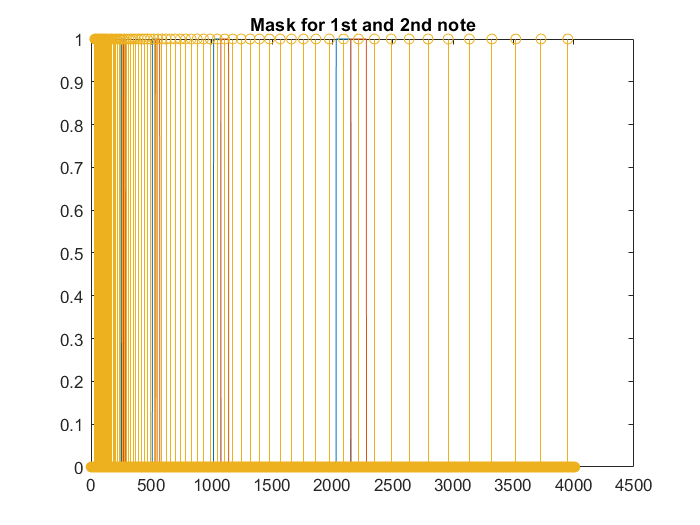

N_spec = floor((NFFT + N_zero) / ds);   % Total count of spectum samples after processing
masks = zeros([NPO, N_spec]);           % Masks for each note

Flat_Index = reshape(Indexes', [1, NOTES]);

for i = 1:NPO
    
    j = 1:OCTAVES;   
        
    if i == NPO
        
        n1 = Indexes(j,i-1);
        n2 = Indexes(j,i);
        dif = floor((n2 - n1)/2);   % Let the distance be equal to the left and rigt of note freqency
        
        for ii = 1:length(n1)
            masks(i, n1(ii)-dif(ii):n1(ii)+dif(ii)) = ones(1, 2*dif(ii)+1);
        end
        
    else
        
        n1 = Indexes(j,i);
        n2 = Indexes(j,i+1);
        dif = floor((n2 - n1)/2);   % Let the distance be equal to the left and rigt of note freqency
        
        for ii = 1:length(n1)
            masks(i, n1(ii)-dif(ii):n1(ii)+dif(ii)) = ones(1, 2*dif(ii)+1);
        end
        
    end
           
end

% Make 0001000 where 1 - represents note frequency
f = zeros([1, N_spec]);
for i = 1:N_spec
    n = find(Flat_Index == i);
    
    if n >= 1
        f(i) = 1;
    else
        f(i) = 0;
    end
end

figure
plot(masks(1,:))
hold on
plot(masks(2,:))
stem(f)
title('Mask for 1st and 2nd note. Stem - freq of notes')